# Denavit - Hartenberg Kinematics

#### Direct Kinematics

clear; clc; close all;
syms(sym('q', [1 3]));

% DH parameters
D=[2 4 0]; A=[1.1 0 1.5]; T=[0 pi/2 -pi/2]; F=[+pi/2 -pi/2 -pi/2];
alpha=pi/6;
P3e=[0;0;0;1];

DHpar=[q1+T(1)  D(1)       A(1)   F(1)-alpha;
       T(2)     q2+D(2)    A(2)   F(2);
       q3+T(3)  D(3)       A(3)   F(3)];

% Define symbloic matrix
M03(q1,q2,q3) = DH_total_matrix(DHpar);

DHdirect = M03*P3e; % Direct kinematics function

% Position of the gripper in the reference system 0 at the initial conditions 
P0e_0=DHdirect(0,0,0)

$$P0e\_0 = \left(\begin{array}{c} \frac{11}{10}\\ -\frac{11\,\sqrt{3}}{4}\\ \frac{19}{4}\\ 1 \end{array}\right)$$

P0e_0=double(DHdirect(0,0,0));

#### Workspace

% Joints variables 
nPoints=[30 5 15];
limits=[-pi pi 0 3 -pi*0.5 pi*0.5];
q1_inf = limits(1); q1_sup = limits(2); q1=linspace(q1_inf,q1_sup,nPoints(1));
q2_inf = limits(3); q2_sup = limits(4); q2=linspace(q2_inf,q2_sup,nPoints(2));
q3_inf = limits(5); q3_sup = limits(6); q3=linspace(q3_inf,q3_sup,nPoints(3));

Q = allCombinations(q1,q2,q3); % all possible combinations of joints variables
tic
for i=1:size(Q,1)
    P(i,:)=double(DHdirect(Q(i,1),Q(i,2),Q(i,3)))';
end
toc

Elapsed time is 18.603630 seconds.


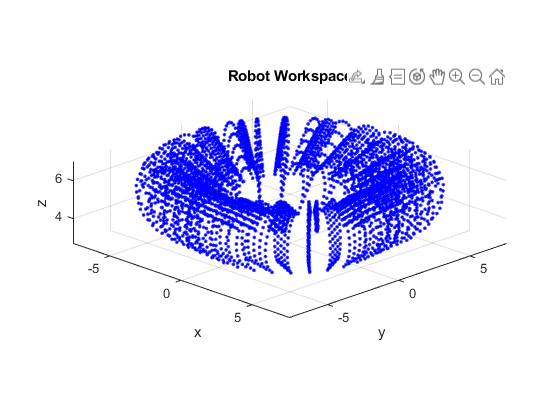


% Plot WS
figure
plot3(P(:,1),P(:,2),P(:,3),'.b');
xlabel('x');ylabel('y');zlabel('z');
title('Robot Workspace')
axis equal; grid on; view(45,20);
p.LineWidth = 3;
% set(gcf,'Visible','on')

#### Inverse Kinematics check

Plot posizione iniziale

figure
plot3(P0e_0(1),P0e_0(2),P0e_0(3),'*r')
hold on

Inverse kinematics

[Q_0,~,~,~] = DHinv(P0e_0,D,A,alpha);
Q_0=double(Q_0)

Q_0 =   -2.6877 + 0.0000i  -6.7500 - 4.5208i   1.5708 - 1.8228i
  -2.6877 + 0.0000i  -6.7500 + 4.5208i  -4.7124 + 1.8228i
   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   3.0000 + 0.0000i  -3.1416 + 0.0000i



for i=1:4    
    Pi(i,:)=double(DHdirect(Q_0(i,1),Q_0(i,2),Q_0(i,3)));
    plot3(Pi(i,1),Pi(i,2),Pi(i,3),'.b')
    err(i) = norm(Pi(i,:)-P0e_0');
    if err(i)<10^-10
        err(i)=0;
    end
end

err

err =      0     0     0     0


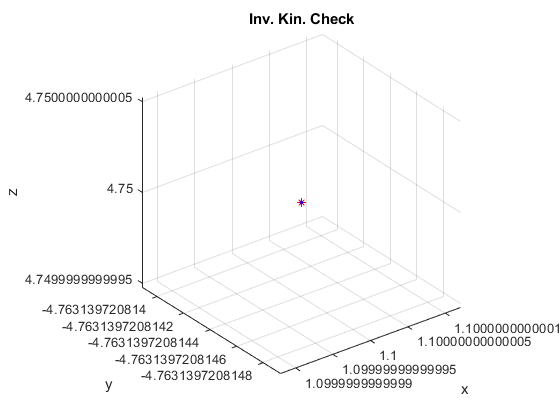

hold off; grid on;
xlabel('x'); ylabel('y'); zlabel('z')
title('Inv. Kin. Check')

% set(gcf,'Visible','on')


Check robot position

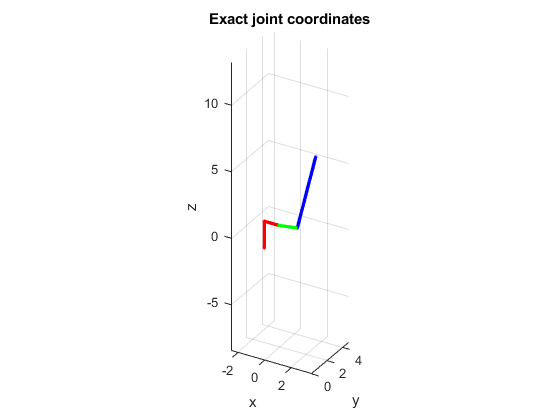

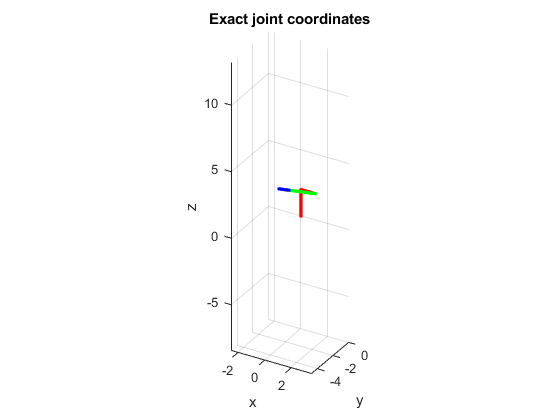

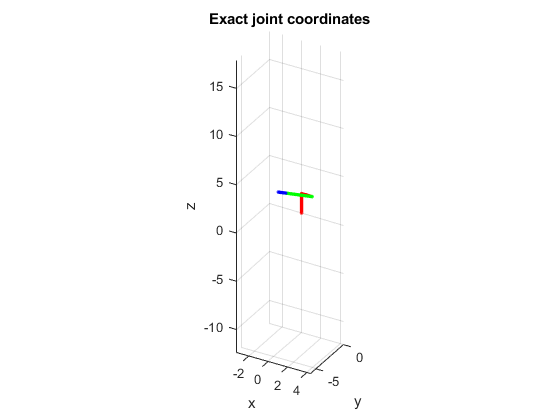

for i=1:size(Q_0,1)
    figure
    DH_plot_robot(Q_0(i,:),D,A,alpha,gcf,DHdirect)
    grid on
    axis equal
    view(30,30)
    xlabel('x'); ylabel('y'); zlabel('z')
    title('Exact joint coordinates')
%     set(gcf,'Visible','on')
end